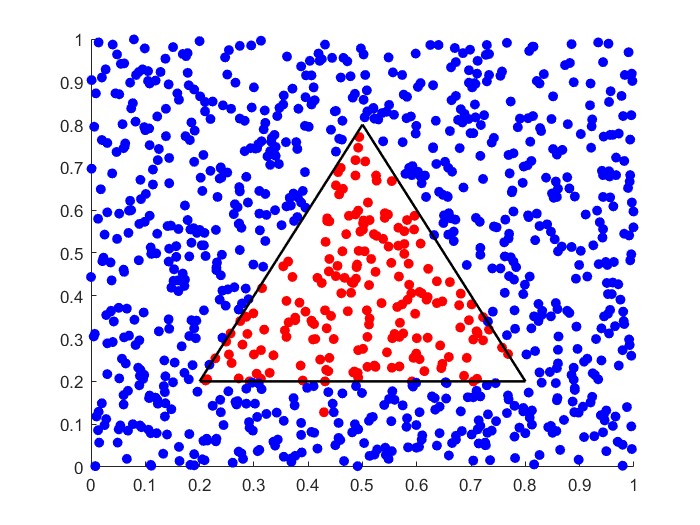

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Driehoek");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];
data = perturbate_triangle_data(data,0.05,1,100);

xunit1 = linspace(0.2,0.8);
xunit2 = linspace(0.2,0.5);
xunit3 = linspace(0.5,0.8);
yunit1 = 0*xunit1 + 0.2;
yunit2 = 2*xunit2 - 0.2;
yunit3 = -2*xunit3 + 1.8;

data_XA = {};
data_YA = {};
data_XB = {};
data_YB = {};

for i = 1:length(data)
    if (data(3,i) == 0) && (data(4,i) == 1) 
        data_XB = [data_XB, data(1,i)];
        data_YB = [data_YB, data(2,i)];
    else
        data_XA = [data_XA, data(1,i)];
        data_YA = [data_YA, data(2,i)];
    end
end

data_XA = cell2mat(data_XA);
data_YA = cell2mat(data_YA);
data_XB = cell2mat(data_XB);
data_YB = cell2mat(data_YB);

figure
hold on
axis([0 1 0 1])
scatter(data_XA,data_YA,'red','filled')
scatter(data_XB,data_YB,'blue','filled')
plot(xunit1, yunit1,'black','LineWidth',1.5);
plot(xunit2, yunit2,'black','LineWidth',1.5);
plot(xunit3, yunit3,'black','LineWidth',1.5);
hold off